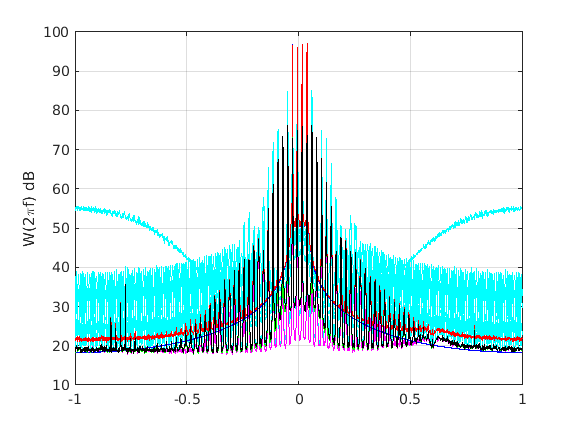

clear all
% 80 'x'=x, 'y'=d, 200 'x'=x, 'y'=y
load('gsm_4c_in'); % K = 201, U(m, t:t+st-1) = [in1(n+k) in1(n+k)*abs(in1(n+k))]; => NMSE = -30.5
load('gsm_4c_out');
% load('linear_lte_2c_data0_in');
% load('linear_lte_2c_data0_out');
% load('linear_lte_2c_data1_in');
% load('linear_lte_2c_data1_out');
% load('lte_2c_data0_in');
% load('lte_2c_data0_out');
% load('lte_2c_data1_in');
% load('lte_2c_data1_out');
% load('lte_4c_data0_in');
% load('lte_4c_data0_out');
% load('lte_10c_data0_in');
% load('lte_10c_data0_out');
in = x.';
out = y.';
e = out - in;
e_new =  zeros(1, length(x));
X = 10*log10(pwelch(in, 2048));
X1(1:length(X)/2) = X(length(X)/2+1:end);
X1(length(X)/2+1:length(X)) = X(1:length(X)/2);
Y = 10*log10(pwelch(out, 2048));
Y1(1:length(Y)/2) = Y(length(Y)/2+1:end);
Y1(length(Y)/2+1:length(Y)) = Y(1:length(Y)/2);
E = 10*log10(pwelch(out-in, 2048));
E1(1:length(E)/2) = E(length(E)/2+1:end);
E1(length(E)/2+1:length(E)) = E(1:length(E)/2);
plot(linspace(-1, 1, length(X1)), X1,'b');
hold on
plot(linspace(-1, 1, length(Y1)), Y1,'r');
hold on
plot(linspace(-1, 1, length(E1)), E1,'g');
ylabel('W(2\pif) dB')
grid on
K = 201; % порядок + 1
in1 = zeros(length(x) + K - 1, 1);
in1(1+(K-1)/2:length(x)+(K-1)/2, 1) = in;
U = zeros(length(x), K*2);
st = 2; % вместе с этим не забудь изменить сам полином
m = 1;
% модель (с дополнением нулями)
for n = (K-1)/2+1:length(in)+(K-1)/2
    t = 1;
    for k = (K-1)/2:-1:-(K-1)/2
        U(m, t:t+st-1) = [in1(n+k) in1(n+k)*abs(in1(n+k))]; % st измени
        t = t + st;
    end
    m = m + 1;
end
% модель (без дополнения нулями) хуже
% for n = (K-1)/2+1:length(in)+(K-1)/2
%     t = 1;
%         for k = (K-1)/2:-1:-(K-1)/2
%             U(m, t:t+st-2) = [in(n+k) in(n+k)*abs(in(n+k))^2 in(n+k)*abs(in(n+k))^4];
%             t = t + st-1;
%         end
%         m=m+1;
% end
Rxx = U'*U; % корреляционная матрица сигнала
rxd = U'*out;
w_opt = pinv(Rxx)*rxd;
z = U*w_opt;
% U =[x(0), x(0)|x(0)|, x(0)*|x(0)|^2, ... x(-1), x(-1)|x(-1)| ... x(1), x(1)|x(1)|...]
e_mod =  out - z;
E_mod = 10*log10(pwelch(e_mod, 2048)); % ошибка ошибки
hold on
E_mod1(1:length(E_mod)/2) = E_mod(length(E_mod)/2+1:end);
E_mod1(length(E_mod)/2+1:length(E_mod)) = E_mod(1:length(E_mod)/2);
plot(linspace(-1, 1, length(E_mod1)), E_mod1,'k');

NMSE= 10*log10((e_mod'*e_mod)/(in'*in));